# Homework 4 Root Locus Walkthrough

This is the maintainable source for HW4_root_locus_walkthrough.mlx.

clear; clc; close all;
format short g;
addpath(genpath(fullfile(pwd, 'scripts')));

## User choices

These are the gains I would change by hand after looking at root locus.

Kq_pick = 0.4;     % pure pitch damper gain
Kv_pick = 0.08;    % outer proportional airspeed gain
Ki_pick = 0.03;    % outer integral airspeed gain

## Find one trim point

The whole point of this section is to remove trim and linearize about a real cruise condition instead of around zeros.

trimPoint = find_trim_point_eul_simple( ...
    'Model', 'Brown_6DOF_Plant_EUL', ...
    'CruiseSpeed', 70, ...
    'DisplayReport', 'off');


apply_trim_point_to_workspace(trimPoint);

trimSummary = table( ...
    trimPoint.inputs.front_collective_rpm, ...
    trimPoint.inputs.rear_collective_rpm, ...
    rad2deg(trimPoint.inputs.delta_e), ...
    rad2deg(trimPoint.eul(2)), ...
    norm(trimPoint.velocity), ...
    'VariableNames', {'front_collective_rpm','rear_collective_rpm','delta_e_deg','theta_deg','vinf_mps'})

trimSummary = 1×5 table
    front_collective_rpm    rear_collective_rpm    delta_e_deg    theta_deg    vinf_mps
    ____________________    ___________________    ___________    _________    ________

           1181.4                    0               -15.06        2.6325         70   


## Linearize the Euler plant at that trim point

load_system('Brown_6DOF_Plant_EUL');
[A, B, C, D] = linmod('Brown_6DOF_Plant_EUL', trimPoint.x0, trimPoint.u0);


io = localIoMap();
s = tf('s');

## Show the state matrices

These are the perturbation matrices around the trim point.

A

A =             0            0            0            1            0            0            0        -1000   3.3578e-18            0            0            0
            0            0            0            0            1            0         1000            0   -2.344e-19            0            0            0
            0            0            0            0            0            1            0            0            0            0            0            0
            0            0            0       815.57      -187.93      -5.9994            0        -9.81            0       10.226       677.47       1607.9
            0            0            0      -194.37       161.99        21.89         9.81            0            0      -892.69       51.713      -1532.9
            0            0            0       2.9436      -47.046      -2.1823            0            0            0       9.6271      -4.1848       29.839
            0            0            0            0  


B

B =             0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
   9.3271e-05   9.3271e-05   9.3271e-05   9.3271e-05   9.

## Open-loop eigenvalues

openLoopPoles = eig(A);
eigTable = table(real(openLoopPoles), imag(openLoopPoles), ...
    'VariableNames', {'real_part','imag_part'})

eigTable = 12×2 table
    real_part    imag_part
    _________    _________

            0           0 
            0           0 
            0           0 
            0           0 
       1620.5           0 
       422.32           0 
      -79.113           0 
       91.401           0 
       41.293           0 
       31.782           0 
    0.0099901      3.2153 
    0.0099901     -3.2153 


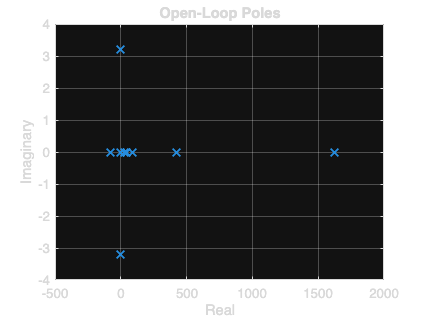


figure('Color', 'w', 'Position', [100 100 560 420]);
plot(real(openLoopPoles), imag(openLoopPoles), 'x', 'LineWidth', 1.5, 'MarkerSize', 8);
grid on;
xlabel('Real');
ylabel('Imaginary');
title('Open-Loop Poles');

## Part A: pure dampers

For the pure damper, the "right" transfer function is rate over control.

Gp = ss(A, B(:, io.inputs.delta_a), C(io.outputs.omega(1), :), D(io.outputs.omega(1), io.inputs.delta_a));
Gq = ss(A, B(:, io.inputs.delta_e), C(io.outputs.omega(2), :), D(io.outputs.omega(2), io.inputs.delta_e));
Gr = ss(A, B(:, io.inputs.delta_r), C(io.outputs.omega(3), :), D(io.outputs.omega(3), io.inputs.delta_r));

roll_damper_tf = minreal(zpk(Gp))


roll_damper_tf =
 
  -107.37 (s-2121) (s-503.7) (s-27.83) (s^2 - 0.009267s + 10.35) (s^2 - 197.3s + 1.305e04)
  ----------------------------------------------------------------------------------------
     (s-1620) (s-422.3) (s-91.4) (s-41.29) (s-31.78) (s+79.11) (s^2 - 0.01998s + 10.34)
 
Continuous-time zero/pole/gain model.


pitch_damper_tf = minreal(zpk(Gq))


pitch_damper_tf =
 
   -263.41 (s-1655) (s-481) (s+74.86) (s^2 - 0.0104s + 10.33) (s^2 - 60.29s + 1695)
  ----------------------------------------------------------------------------------
  (s-1620) (s-422.3) (s-91.4) (s-41.29) (s-31.78) (s+79.11) (s^2 - 0.01998s + 10.34)
 
Continuous-time zero/pole/gain model.


yaw_damper_tf = minreal(zpk(Gr))


yaw_damper_tf =
 
  342.08 (s-711.7) (s+364.8) (s-109.4) (s-79.35) (s-4.473) (s^2 - 0.01847s + 10.34)
  ----------------------------------------------------------------------------------
  (s-1620) (s-422.3) (s-91.4) (s-41.29) (s-31.78) (s+79.11) (s^2 - 0.01998s + 10.34)
 
Continuous-time zero/pole/gain model.


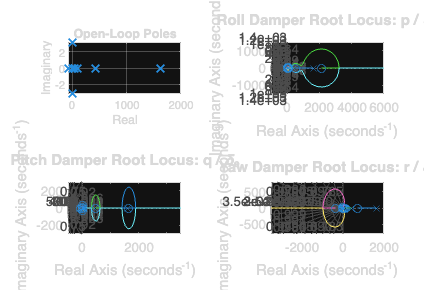


figure('Color', 'w', 'Position', [100 100 1200 820]);
tiledlayout(2,2);

nexttile;
plot(real(openLoopPoles), imag(openLoopPoles), 'x', 'LineWidth', 1.5, 'MarkerSize', 8);
grid on;
xlabel('Real');
ylabel('Imaginary');
title('Open-Loop Poles');

nexttile;
rlocus(Gp);
grid on;
title('Roll Damper Root Locus: p / \delta_a');

nexttile;
rlocus(Gq);
grid on;
title('Pitch Damper Root Locus: q / \delta_e');

nexttile;
rlocus(Gr);
grid on;
title('Yaw Damper Root Locus: r / \delta_r');

## Choose one pitch damper gain

Change Kq_pick above and rerun this section.

if ~exist('Kq_pick', 'var')
    Kq_pick = 0.4;
end
A_q = A - B(:, io.inputs.delta_e) * Kq_pick * C(io.outputs.omega(2), :);
qDamperPoles = eig(A_q);
qDamperPoleTable = table(real(qDamperPoles), imag(qDamperPoles), ...
    'VariableNames', {'real_part','imag_part'})

qDamperPoleTable = 12×2 table
    real_part    imag_part
    _________    _________

           0            0 
           0            0 
           0            0 
           0            0 
        1618            0 
      386.43            0 
       244.7            0 
     -77.394            0 
      30.885       22.218 
      30.885      -22.218 
    0.007054       3.2144 
    0.007054      -3.2144 


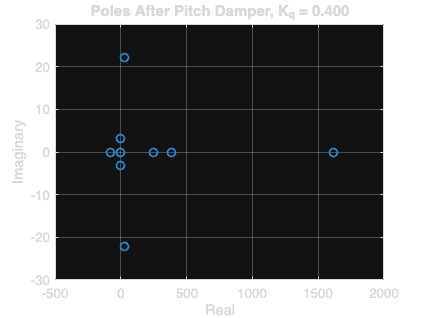


figure('Color', 'w', 'Position', [100 100 560 420]);
plot(real(qDamperPoles), imag(qDamperPoles), 'o', 'LineWidth', 1.2, 'MarkerSize', 6);
grid on;
xlabel('Real');
ylabel('Imaginary');
title(sprintf('Poles After Pitch Damper, K_q = %.3f', Kq_pick));

## Part B: lock in the damper, then add proportional airspeed control

I am using the airspeed option here.

GV_qdamped = ss(A_q, B(:, io.inputs.front_collective), ...
    C(io.outputs.vinf, :), D(io.outputs.vinf, io.inputs.front_collective));

airspeed_p_tf = minreal(zpk(GV_qdamped))


airspeed_p_tf =
 
     0.0022931 (s-3824) (s-90.53) (s^2 - 0.01149s + 10.34) (s^2 + 244.9s + 4.865e04)
  -------------------------------------------------------------------------------------
  (s-1618) (s-386.4) (s-244.7) (s+77.39) (s^2 - 0.01411s + 10.33) (s^2 - 61.77s + 1448)
 
Continuous-time zero/pole/gain model.


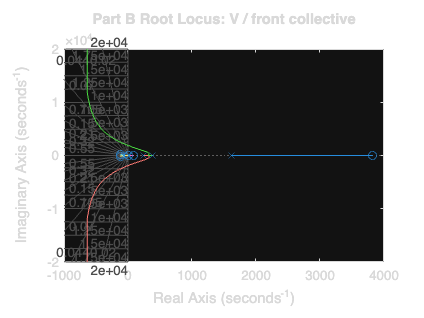


figure('Color', 'w', 'Position', [100 100 560 420]);
rlocus(GV_qdamped);
grid on;
title('Part B Root Locus: V / front collective');

## Choose one proportional airspeed gain

Change Kv_pick above and rerun this section.

if ~exist('Kv_pick', 'var')
    Kv_pick = 0.08;
end
A_v = A_q - B(:, io.inputs.front_collective) * Kv_pick * C(io.outputs.vinf, :);
pdPoles = eig(A_v);
pdPoleTable = table(real(pdPoles), imag(pdPoles), ...
    'VariableNames', {'real_part','imag_part'})

pdPoleTable = 12×2 table
    real_part    imag_part
    _________    _________

           0            0 
           0            0 
           0            0 
           0            0 
        1618            0 
      386.43            0 
       244.7            0 
     -77.394            0 
      30.885       22.218 
      30.885      -22.218 
    0.007054       3.2144 
    0.007054      -3.2144 


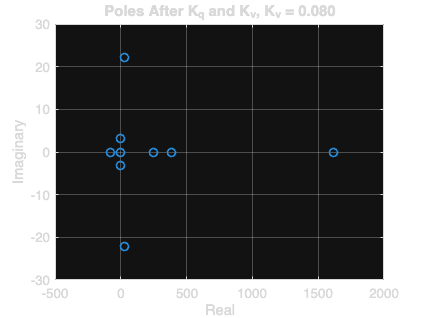


figure('Color', 'w', 'Position', [100 100 560 420]);
plot(real(pdPoles), imag(pdPoles), 'o', 'LineWidth', 1.2, 'MarkerSize', 6);
grid on;
xlabel('Real');
ylabel('Imaginary');
title(sprintf('Poles After K_q and K_v, K_v = %.3f', Kv_pick));

## Part C: add integral action on airspeed

Keep the proportional airspeed gain from part B and then add I.

GV_pd_base = ss(A_v, B(:, io.inputs.front_collective), ...
    C(io.outputs.vinf, :), D(io.outputs.vinf, io.inputs.front_collective));
GVI = minreal(GV_pd_base / s);

4 states removed.


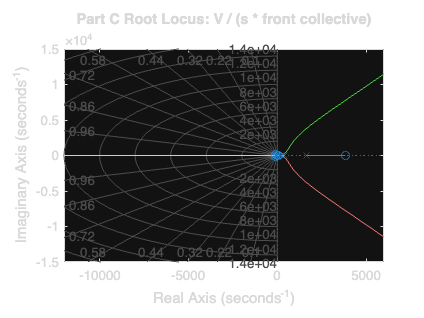


figure('Color', 'w', 'Position', [100 100 560 420]);
rlocus(GVI);
grid on;
title('Part C Root Locus: V / (s * front collective)');

## Choose one integral gain

Change Ki_pick above and rerun this section.

if ~exist('Ki_pick', 'var')
    Ki_pick = 0.03;
end
A_pi = [A_v, zeros(size(A_v, 1), 1); -C(io.outputs.vinf, :), 0];
B_pi = [B(:, io.inputs.front_collective); 0];

piPoles = eig(A_pi - B_pi * Ki_pick * [zeros(1, size(A_v, 1)), 1]);
piPoleTable = table(real(piPoles), imag(piPoles), ...
    'VariableNames', {'real_part','imag_part'})

piPoleTable = 13×2 table
     real_part     imag_part
    ___________    _________

              0           0 
              0           0 
              0           0 
              0           0 
           1618           0 
         386.43           0 
          244.7           0 
        -77.394           0 
         30.885      22.218 
         30.885     -22.218 
       0.007054      3.2144 
       0.007054     -3.2144 
    -6.7645e-08           0 


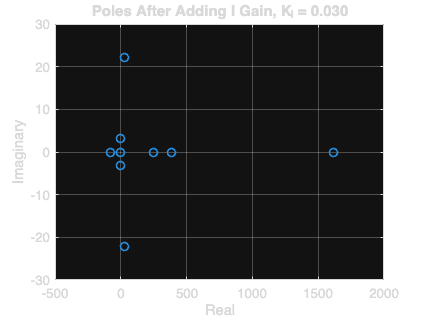


figure('Color', 'w', 'Position', [100 100 560 420]);
plot(real(piPoles), imag(piPoles), 'o', 'LineWidth', 1.2, 'MarkerSize', 6);
grid on;
xlabel('Real');
ylabel('Imaginary');
title(sprintf('Poles After Adding I Gain, K_i = %.3f', Ki_pick));

## Gain summary

gainSummary = table(Kq_pick, Kv_pick, Ki_pick)

gainSummary = 1×3 table
    Kq_pick    Kv_pick    Ki_pick
    _______    _______    _______

      0.4       0.08       0.03  



function io = localIoMap()
io = struct();
io.inputs.motor = 1:12;
io.inputs.tilt = 13:18;
io.inputs.front_collective = 19;
io.inputs.rear_collective = 20;
io.inputs.delta_f = 21;
io.inputs.delta_a = 22;
io.inputs.delta_e = 23;
io.inputs.delta_r = 24;

io.outputs.pos = 1:3;
io.outputs.v_b = 4:6;
io.outputs.v_e = 7:9;
io.outputs.eul = 10:12;
io.outputs.omega = 13:15;
io.outputs.C_NB = 16:24;
io.outputs.v_ba = 25:27;
io.outputs.vinf = 28;
io.outputs.alpha = 29;
io.outputs.beta = 30;
io.outputs.specific_force = 31:33;
end